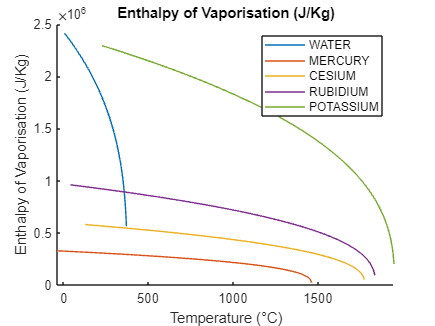

%% Graphs

min_Tx = min(Tx);
max_Tx = max(Tx);

x5 = 1;

Hvx_fig = figure;
axes1 = axes('Parent',Hvx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),Hvx(:,x5),'Parent',axes1);
set(plot1,'DisplayName',NAME(x5));
end
title('Enthalpy of Vaporisation (J/Kg)');
ylabel({'Enthalpy of Vaporisation (J/Kg)'});                           
xlabel({'Temperature (°C)'}); 
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

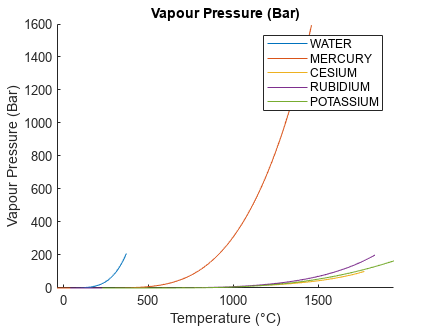



Pvx_fig = figure;
axes1 = axes('Parent',Pvx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),Pvx(:,x5),'Parent',axes1); 
set(plot1,'DisplayName',NAME(x5));
end
title('Vapour Pressure (Bar)');
ylabel({'Vapour Pressure (Bar)'});                           
xlabel({'Temperature (°C)'}); 
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

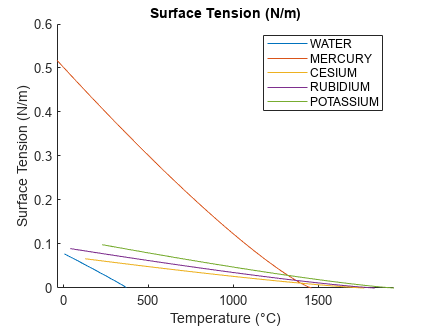



stx_fig = figure;
axes1 = axes('Parent',stx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),stx(:,x5),'Parent',axes1); 
set(plot1,'DisplayName',NAME(x5));
end
title('Surface Tension (N/m)');
ylabel({'Surface Tension (N/m)'});                           
xlabel({'Temperature (°C)'}); 
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

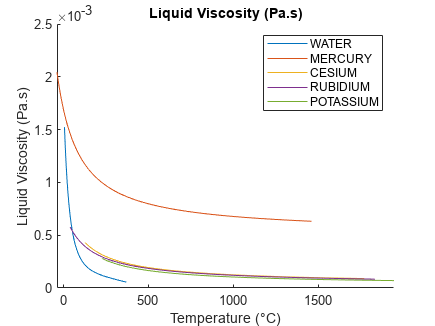



vlx_fig = figure;
axes1 = axes('Parent',vlx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),vlx(:,x5),'Parent',axes1);
set(plot1,'DisplayName',NAME(x5));
end
title('Liquid Viscosity (Pa.s)');
ylabel({'Liquid Viscosity (Pa.s)'});                           
xlabel({'Temperature (°C)'});
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

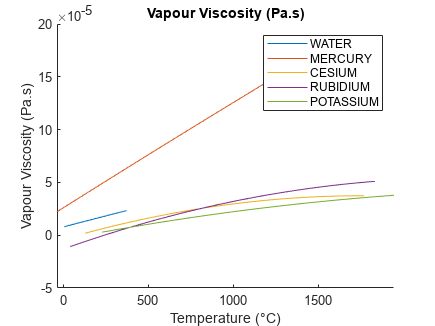



vvx_fig = figure;
axes1 = axes('Parent',vvx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),vvx(:,x5),'Parent',axes1); 
set(plot1,'DisplayName',NAME(x5));
end
title('Vapour Viscosity (Pa.s)');
ylabel({'Vapour Viscosity (Pa.s)'});                           
xlabel({'Temperature (°C)'});
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

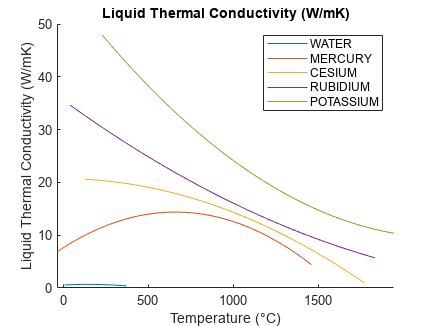



% Klx_fig = figure;
% axes1 = axes('Parent',Klx_fig);
% hold(axes1,'on');
% for x5 = 1:n;
% plot1 = plot(Tx(:,x5),Klx(:,x5),'Parent',axes1); 
% set(plot1,'DisplayName',NAME(x5));
% end
% title('Liquid Thermal Conductivity (W/mK)');
% ylabel({'Liquid Thermal Conductivity (W/mK)'});                           
% xlabel({'Temperature (°C)'});
% legend1 = legend(axes1,'show');
% xlim(axes1,[min(min_Tx) max(max_Tx)]);
% set(legend1,'Location','northeast');

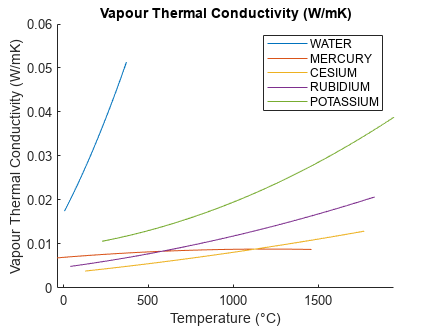

% 
% 
% Kvx_fig = figure;
% axes1 = axes('Parent',Kvx_fig);
% hold(axes1,'on');
% for x5 = 1:n;
% plot1 = plot(Tx(:,x5),Kvx(:,x5),'Parent',axes1); 
% set(plot1,'DisplayName',NAME(x5));
% end
% title('Vapour Thermal Conductivity (W/mK)');
% ylabel({'Vapour Thermal Conductivity (W/mK)'});                           
% xlabel({'Temperature (°C)'});
% legend1 = legend(axes1,'show');
% xlim(axes1,[min(min_Tx) max(max_Tx)]);
% set(legend1,'Location','northeast');

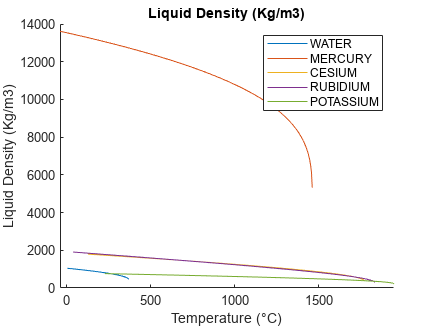



dlx_fig = figure;
axes1 = axes('Parent',dlx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),dlx(:,x5),'Parent',axes1); 
set(plot1,'DisplayName',NAME(x5));
end
title('Liquid Density (Kg/m3)');
ylabel({'Liquid Density (Kg/m3)'});                           
xlabel({'Temperature (°C)'});
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

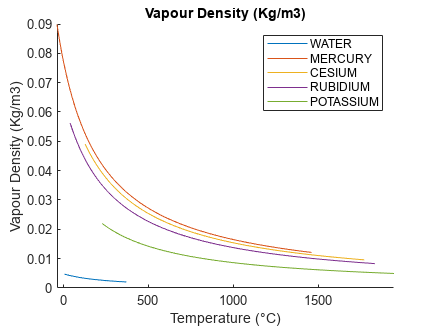



dvx_fig = figure;
axes1 = axes('Parent',dvx_fig);
hold(axes1,'on');
for x5 = 1:n;
plot1 = plot(Tx(:,x5),dvx(:,x5),'Parent',axes1); 
set(plot1,'DisplayName',NAME(x5));
end
title('Vapour Density (Kg/m3)');
ylabel({'Vapour Density (Kg/m3)'});                           
xlabel({'Temperature (°C)'});
legend1 = legend(axes1,'show');
xlim(axes1,[min(min_Tx) max(max_Tx)]);
set(legend1,'Location','northeast');

Outputs

% Hvx data

x5=1;
for x5 = 1:n;
Hvx_data = [Hvx(:,x5)];
Hvx_data_x(:,x5) = Hvx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
Hvx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),Hvx_data_x(:,x6)]);
x5 = x5+2;
    end
end


% Pvx data

x5=1;
for x5 = 1:n;
Pvx_data = [Pvx(:,x5)];
Pvx_data_x(:,x5) = Pvx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
Pvx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),Pvx_data_x(:,x6)]);
x5 = x5+2;
    end
end



% stx data

x5=1;
for x5 = 1:n;
stx_data = [stx(:,x5)];
stx_data_x(:,x5) = stx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
stx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),stx_data_x(:,x6)]);
x5 = x5+2;
    end
end



% vvx data

x5=1;
for x5 = 1:n;
vvx_data = [vvx(:,x5)];
vvx_data_x(:,x5) = vvx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
vvx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),vvx_data_x(:,x6)]);
x5 = x5+2;
    end
end



% vlx data

x5=1;
for x5 = 1:n;
vlx_data = [vlx(:,x5)];
vlx_data_x(:,x5) = vlx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
vlx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),vlx_data_x(:,x6)]);
x5 = x5+2;
    end
end


% Klx data

x5=1;
for x5 = 1:n;
Klx_data = [Klx(:,x5)];
Klx_data_x(:,x5) = Klx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
Klx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),Klx_data_x(:,x6)]);
x5 = x5+2;
    end
end

% Kvx data

x5=1;
for x5 = 1:n;
Kvx_data = [Kvx(:,x5)];
Kvx_data_x(:,x5) = Kvx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
Kvx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),Kvx_data_x(:,x6)]);
x5 = x5+2;
    end
end



% dlx data

x5=1;
for x5 = 1:n;
dlx_data = [dlx(:,x5)];
dlx_data_x(:,x5) = dlx_data;
end

x5=1;
while x5 < n*2;
    for x6 = 1:n;
dlx_data_xx(:,[x5,x5+1]) = real([Tx(:,x6),dlx_data_x(:,x6)]);
x5 = x5+2;
    end
end